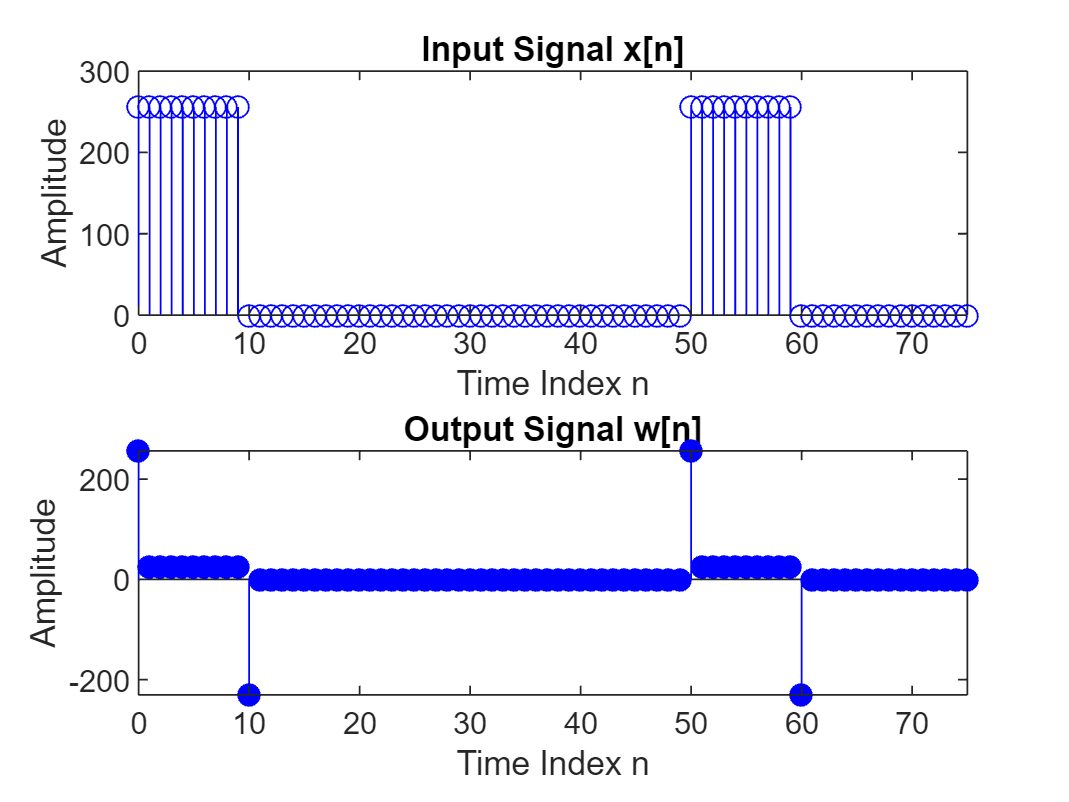

% Deconvolution for 1-D filters
xx = 256 * (rem(0:100, 50) < 10); %signal
bb = [1, -0.9]; % Filter coefficients

% Filtering
w = firfilt(bb, xx);

% Plotting
figure;
subplot(2,1,1);
stem(0:100, xx, 'b');
title('Input Signal x[n]');
xlabel('Time Index n'); ylabel('Amplitude');
xlim([0 75]);

subplot(2,1,2);
stem(0:length(w)-1, w, 'filled', 'b');
title('Output Signal w[n]');
xlabel('Time Index n'); ylabel('Amplitude');
xlim([0 75]);


% Display the lengths of the signals
disp(['Length of x[n]: ', num2str(length(xx))]);

Length of x[n]: 101


disp(['Length of w[n]: ', num2str(length(w))]);

Length of w[n]: 102


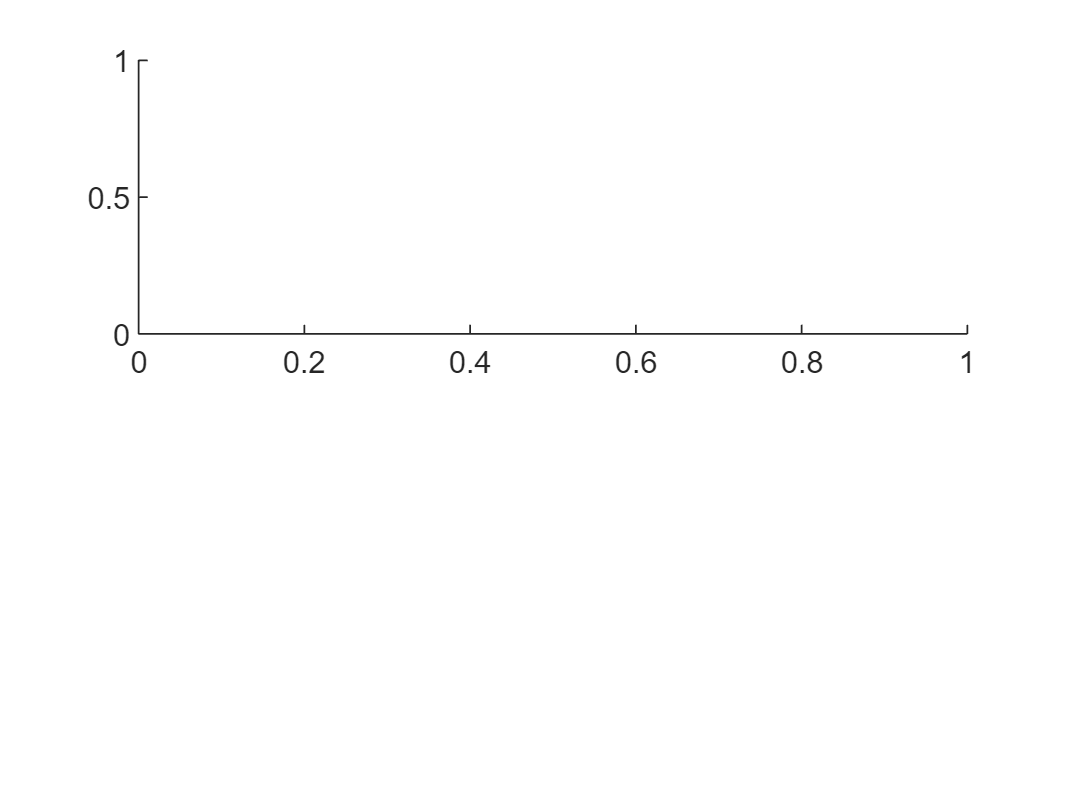


%--------------------------------------
%3.1 RESTORATION
rr = 0.9.^(0:22); % Filter coefficients for restoration filter
zz = firfilt(rr, xx);

% Plot the input and output signals
figure;
subplot(2,1,1);

stem(0:length(yy)-1, yy);

Unrecognized function or variable 'yy'.

title('Distorted Signal');
xlabel('Time Index (n)');
ylabel('Amplitude');

subplot(2,1,2);
stem(0:length(zz)-1, zz, 'filled');
title('Restored Signal');
xlabel('Time Index (n)');
ylabel('Amplitude');

% Display the lengths of the signals
disp(['Length of x[n]: ', num2str(length(xx))]);
disp(['Length of w[n]: ', num2str(length(ww))]);
disp(['Length of y[n]: ', num2str(length(yy))]);

